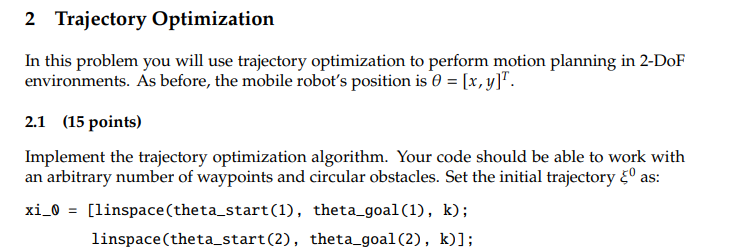

clear
close all

% Start and Goal orientations
theta_start = [0;0];
theta_goal = [1;1];

% Initial trajectory variables
n = 2; % No. of joints / 2-D trajectory
k = 10; % No. of waypoints

% Obstacle Parameters - add obstacles as needed
% Each row: [center_x, center_y, radius]
obstacles = [
    0.55, 0.5, 0.3;  % First obstacle
    % Add more obstacles here, e.g., [x, y, r]
];

xi_0 = [linspace(theta_start(1), theta_goal(1), k);
        linspace(theta_start(2), theta_goal(2), k)];

xi_0_vec = reshape(xi_0, [], 1);

% Equality constraints for start and goal positions
A = [eye(n), zeros(n,n*(k-1)) ;...
     zeros(n,n*(k-1)), eye(n) ];
B = [theta_start;theta_goal];

% Nonlinear optimization
options = optimoptions('fmincon','Display','iter',...   
    'Algorithm','sqp','MaxFunctionEvaluations',1e4);
xi_star_vec = fmincon(@(xi) cost(xi, obstacles), xi_0_vec, ...
    [], [], A, B, [], [], @(xi) nonlcon(xi, obstacles), options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          21    2.406330e+03     2.442e-01     1.000e+00     0.000e+00     9.306e+04  
    1          65    1.363684e+03     2.844e-03     2.737e-04     2.567e+01     1.033e+02  
    2          88    1.336296e+03     0.000e+00     4.900e-01     3.312e+01     4.955e+01  
    3         110    9.947275e+02     0.000e+00     7.000e-01     2.670e+01     3.330e+01  
    4         132    9.093469e+02     0.000e+00     7.000e-01     2.865e+01     2.909e+01  
    5         154    7.748821e+02     0.000e+00     7.000e-01     2.120e+01     4.364e+01  
    6         176    5.391986e+02     0.000e+00     7.000e-01     1.920e+01     3.179e+01  
    7         198    3.956808e+02     0.000e+00     7.000e-01     1.285e+01     2.076e+01  
    8         220    3.798429e+02     0.000e+00     7.000e-01     9.370e+00     1.

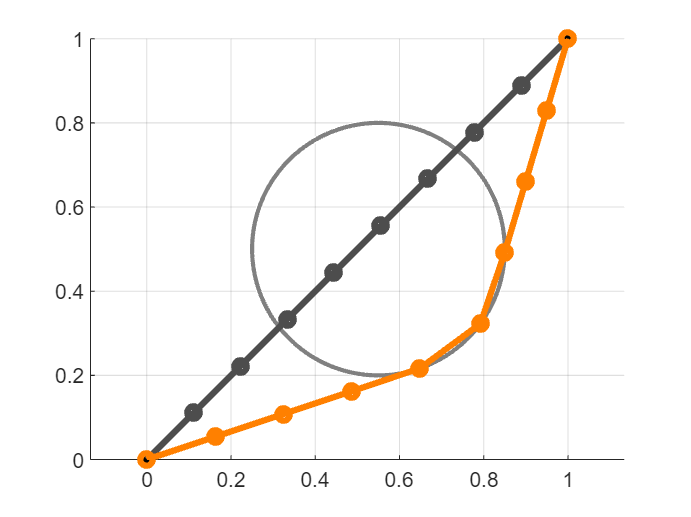

xi_star = reshape(xi_star_vec, 2, []);

% Plotting
figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal
% Plot Obstacles
for i = 1:size(obstacles, 1)
    viscircles(obstacles(i, 1:2), obstacles(i, 3), 'Color', [0.5, 0.5, 0.5]);
end
plot(theta_start(1), theta_start(2), 'ko', 'MarkerFaceColor', 'k')
plot(theta_goal(1), theta_goal(2), 'ko', 'MarkerFaceColor', 'k')
% Plot Result
plot(xi_0(1,:), xi_0(2,:), 'o-', 'Color', [0.3, 0.3, ...
 0.3], 'LineWidth', 3);
plot(xi_star(1,:), xi_star(2,:), 'o-', 'Color', [1, 0.5, 0], 'LineWidth', 3);


% Cost function to minimize

function C = cost(xi, obstacles)
    gamma = 20;
    xi = reshape(xi, 2, []);
    C = 0;

    for idx = 2:length(xi)
        Urep = 0;
        for obs_idx = 1:size(obstacles, 1)
            r = obstacles(obs_idx, 3);
            center = obstacles(obs_idx, 1:2)';
            
            if norm(center - xi(:, idx)) <= r
                Urep = Urep + 0.5 * gamma * ((1 / norm(center - xi(:, idx))) - (1 / r))^2;
            end
        end

        C = C + norm(xi(:, idx) - xi(:, idx - 1))^2 + Urep;
    end
end

% Nonlinear constraints (optional)
function [c, ceq] = nonlcon(xi, obstacles)
    xi = reshape(xi, 2, []);
    c = [];
    for idx = 1:length(xi)
        for obs_idx = 1:size(obstacles, 1)
            r = obstacles(obs_idx, 3);
            center = obstacles(obs_idx, 1:2)';
            dist = norm(xi(:, idx) - center);
            
            % Add a constraint for each obstacle
            c = [c; r - dist];
        end
    end
    ceq = [];
end